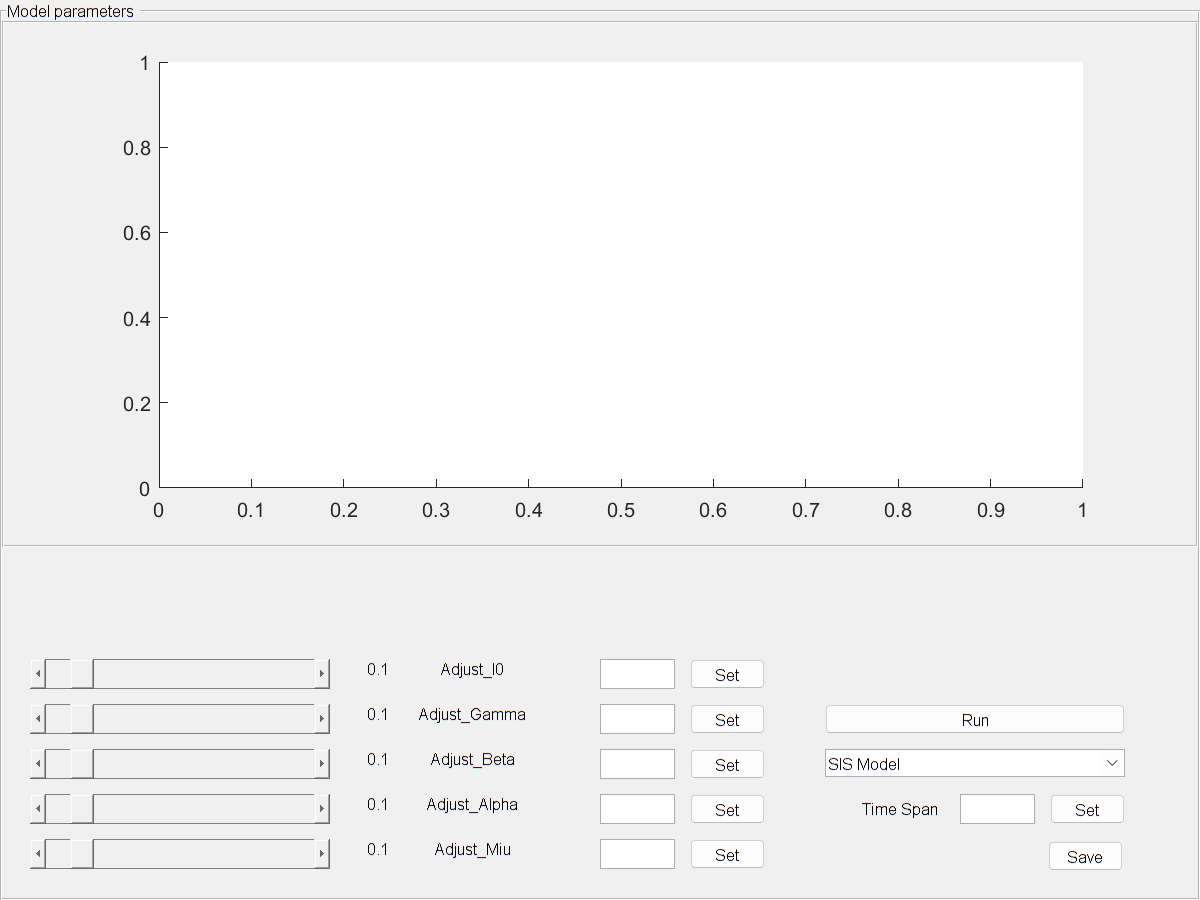

% Main panel and sub panel
set(gcf, 'Position', [100, 100, 800, 600])
main_panel = uipanel('Title', 'Model parameters');
sub_panel = uipanel(main_panel, 'Position', [0.0 0.4 1 0.6]);
chart_axes = axes(sub_panel);

% Drop-down menu
function_list = {'SIS Model', 'SIRS Model','SIR Model'};
function_select = uicontrol(main_panel, 'Style', 'popupmenu', ...
                                        'String', function_list, ...
                                        'Position', [550 80 200 20]);

% List of parameters and initial intervals
parameters = {'Miu', 0.1;                   %DethRate
              'Alpha', 0.1;                 %BirthRate
              'Beta', 0.1;                  %InfectionRate
              'Gamma', 0.1;                 %RecoveryRate
              'I0', 0.1};                   %InitialInfected


% Sliders, titles of edit fields, buttons, display value
for i = 1:size(parameters, 1)
    % Slider
    slider_name = strcat(parameters{i,1}, 'Slider');
    eval([slider_name ' = uicontrol(main_panel, ''Style'', ''slider'', ' ...
                                                '''Min'', 0, ' ...
                                                '''Max'', 1, ' ...
                                                '''Value'', parameters{i,2}, ' ...
                                                '''Position'', [20 20+30*(i-1) 200 20], ' ...
                                                '''String'', parameters{i,1});']);
    
    % Title
    title_name = strcat(parameters{i,1}, 'Text');
    eval([title_name ' = uicontrol(main_panel, ''Style'', ''text'', ' ...
                                               '''String'', strcat(''Adjust_ '', parameters{i,1}), ' ...
                                               '''Position'', [240 20+30*(i-1) 150 20]);']);
    
    % Edit field
    edit_name = strcat(parameters{i,1}, 'Edit');
    eval([edit_name ' = uicontrol(main_panel, ''Style'', ''edit'', ' ...
                                              '''Position'', [400 20+30*(i-1) 50 20]);']);
    
    % Edit field button
    button_name = strcat(parameters{i,1}, 'Button');
    eval([button_name ' = uicontrol(main_panel, ''Style'', ''pushbutton'', ' ...
                                                '''String'', ''Set'', ' ...
                                                '''Position'', [460 20+30*(i-1) 50 20], ' ...
                                                '''Callback'', {@update_button_callback, eval(slider_name), eval(edit_name)});']);
    
    % Display Slider value
    value_name = strcat(parameters{i,1}, 'Value');
    eval([value_name ' = uicontrol(main_panel, ''Style'', ''text'', ' ...
                                               '''String'', num2str(get(eval(slider_name), ''Value'')), ' ...
                                               '''Position'', [230 20+30*(i-1) 45 20]);']);
    
    % Callback to function to refresh values after button press
    set(eval(button_name), 'Callback', {@update_button_callback, eval(slider_name), eval(edit_name), eval(value_name)});
    % Callback to function to refresh values after slider moved
    set(eval(slider_name), 'Callback', {@update_slider_callback, eval(value_name)});
end


% Time span selection field

timeSpan_edit = uicontrol(main_panel, 'Style', 'edit', ...
                                      'Position', [640 50 50 20]);

timeSpan_title = uicontrol(main_panel, 'Style', 'text', ...
                                       'String', 'Time Span', ...
                                       'Position', [565 47 70 20]);

timeSpan_button = uicontrol(main_panel, 'Style', 'pushbutton', ...
                                        'String', 'Set', ...
                                        'Position', [700 50 50 20], ...
                                        'Callback', {@tspan_update_button_callback, timeSpan_edit});


% Run Simulation button
run_button = uicontrol(main_panel, 'Style', 'pushbutton', ...
                                   'String', 'Run', ...
                                   'Position', [550 110 200 20], ...
                                   'Callback', {@run_simulation, function_list, function_select, ...
                                               I0Slider,AlphaSlider,BetaSlider,GammaSlider,MiuSlider,chart_axes,timeSpan_edit});
% Save Figure to PNG button
save_button = uicontrol('Style', 'pushbutton', ...
                        'String', 'Save', ...
                        'Position', [700 20 50 20], ...
                        'Callback', @saveButton_Callback);

function run_simulation(src, event, function_list, function_select,I0Slider,AlphaSlider,BetaSlider,GammaSlider,MiuSlider,chart_axes,timeSpan_edit)
    % Retrieving the selected function from the list
    selected_function = function_list{function_select.Value};

    switch selected_function
        case 'SIS Model'
            sis_model(src, event, I0Slider,BetaSlider,GammaSlider,chart_axes,timeSpan_edit);
        case 'SIRS Model'
            sirs_model(src, event, I0Slider,AlphaSlider,BetaSlider,GammaSlider,MiuSlider,chart_axes,timeSpan_edit);
        case 'SIR Model'
            sir_model(src, event, I0Slider,AlphaSlider,BetaSlider,GammaSlider,chart_axes,timeSpan_edit);
    end
end

function update_button_callback(hObject, eventdata, slider_handle, edit_handle, value_handle)
    % Retrieving the value of the edit field
    value = get(edit_handle, 'String');
    % Checking if the input is a number
    if ~isempty(regexp(value, '-?\d*.{0,1}\d*$','once'))
        new_value = str2double(value);
    else
        % Error message
        msgbox("Please enter a number");
        return;
    end

    % Retrieving the minimum and maximum values of the sliders
    min_value = get(slider_handle, 'Min');
    max_value = get(slider_handle, 'Max');
    
    % Checking if the input number is valid
    if isnan(new_value)
        msgbox("Please enter a valid number.");
        return;
    end
    
    % Checking if the value falls within the range
    if new_value < min_value
        new_value = min_value;
        msgbox("Enter a value within the range. It must be between " + min_value + ":" + max_value + ". Set to (" + min_value + ").");
    elseif new_value > max_value
        new_value = max_value;
        msgbox("Enter a value within the range. It must be between " + min_value + ":" + max_value + ". Set to (" + max_value + ").");
    end
    
    % Refreshing the slider position values
    set(slider_handle, 'Value', new_value);
    
    % Refreshing the display value
    set(value_handle, 'String', strcat(num2str(new_value)));
end


function update_slider_callback(hObject, eventdata, value_handle)
    % Retrieving the value of the slider
    current_value = get(hObject, 'Value');
    
    % Refreshing the display value
    set(value_handle, 'String', num2str(current_value));

end

function sis_model(hObject, eventdata, I0Slider,BetaSlider,GammaSlider,chart_axes,timeSpan_handle) 
    initialInfected = get(I0Slider,'Value');
    infectionRate = get(BetaSlider,'Value');
    recoveryRate = get(GammaSlider,'Value');
    initialSusceptible = 1 - initialInfected;
    initialConditions = [initialSusceptible; initialInfected];
    options = odeset('RelTol',1e-6);
    timeSpan = [0, get(timeSpan_handle, 'Value')];
    stateChangeFunction = @(t,y) [-infectionRate*y(1)*y(2) + recoveryRate*y(2);
                                 infectionRate*y(1)*y(2) - recoveryRate*y(2)];
    [time, states] = ode45(stateChangeFunction,timeSpan,initialConditions,options);
    cla(chart_axes);
    plot(chart_axes,time,states(:,1),'b',time,states(:,2),'r');
    legend(chart_axes,'Number of susceptible', 'Number of infected');
end

function sirs_model(hObject, eventdata, I0Slider,AlphaSlider,BetaSlider,GammaSlider,MiuSlider,chart_axes,timeSpan_handle)
    initialInfected = get(I0Slider,'Value');
    birthRate = get(AlphaSlider,'Value');
    infectionRate = get(BetaSlider,'Value');
    recoveryRate = get(GammaSlider,'Value');
    deathRate = get(MiuSlider,'Value');
    initialSusceptible = 1 - initialInfected;
    initialRecovered = 0;
    initialDead = 0;
    initialConditions = [initialSusceptible; initialInfected; initialRecovered; initialDead];
    options = odeset('RelTol',1e-6);
    timeSpan = [0, get(timeSpan_handle, 'Value')];
    stateChangeFunction = @(t,y) [birthRate - infectionRate*y(1)*y(2) + recoveryRate*y(3) - deathRate*y(1); 
                                  infectionRate*y(1)*y(2) - recoveryRate*y(2) - deathRate*y(2); 
                                  recoveryRate*y(2) - deathRate*y(3); 
                                  deathRate*y(2)];
    [time, states] = ode45(stateChangeFunction,timeSpan,initialConditions,options);
    cla(chart_axes);
    plot(chart_axes,time,states(:,1),'b',time,states(:,2),'r',time,states(:,3),'g',time,states(:,4),'k');
    legend(chart_axes,'Number of susceptible', 'Number of infected', 'Number of recovered', 'Number of deceased');
end



function sir_model(hObject, eventdata, I0Slider,AlphaSlider,BetaSlider,GammaSlider,chart_axes,timeSpan_handle)
    initialInfected = get(I0Slider,'Value');
    birthRate = get(AlphaSlider,'Value');
    infectionRate = get(BetaSlider,'Value');
    recoveryRate = get(GammaSlider,'Value');
    initialSusceptible = 1 - initialInfected;
    initialRecovered = 0;
    initialConditions = [initialSusceptible; initialInfected; initialRecovered];
    options = odeset('RelTol',1e-6);
    timeSpan = [0, get(timeSpan_handle, 'Value')];
    stateChangeFunction = @(t,y) [birthRate - infectionRate*y(1)*y(2);
                                  infectionRate*y(1)*y(2) - recoveryRate*y(2);
                                  recoveryRate*y(2)];
    [time, states] = ode45(stateChangeFunction,timeSpan,initialConditions,options);
    cla(chart_axes);
    plot(chart_axes,time,states(:,1),'b',time,states(:,2),'r',time,states(:,3),'g');
    legend(chart_axes,'Number of susceptible', 'Number of infected', 'Number of recovered');
end

function tspan_update_button_callback(hObject, eventdata, timeSpan_handle)
    value = get(timeSpan_handle, 'String');
    new_value = str2double(value);

    if isnan(new_value)
        msgbox("Please enter a valid number");
        return;
    elseif new_value <= 0
        msgbox("Please enter a value larger than 0");
        return;
    end

    set(timeSpan_handle, 'String', strcat(num2str(new_value)));
    set(timeSpan_handle, 'Value', new_value);
    test = get(timeSpan_handle, 'String');
    fprintf('timeSpan set to %s\n', test)
end

function saveButton_Callback(hObject, eventdata)

   [file, path] = uiputfile('*.png', 'Save Figure as');
   if isequal(file, 0) || isequal(path, 0)
      return;
   end

   saveas(gcf, fullfile(path, file));
end


